pointCloud = readtable('D:\TechnicalReport\DensityField.csv');
pointCloud.Properties.VariableNames = {'X_mm', 'Y_mm', 'Z_mm', 'Density'};

% 3D Interp
x = pointCloud.X_mm;
y = pointCloud.Y_mm;
z = pointCloud.Z_mm;
infill = pointCloud.Density;

n = 200;
xq = linspace(min(x), max(x), n);
yq = linspace(min(y), max(y), n);
dx = (max(x)-min(x))/(n-1);

% Estimate z for square voxels
nz = round((max(z) - min(z))/dx) + 1;
zq = linspace(min(z), max(z), nz);

[Xq, Yq, Zq] = meshgrid(xq, yq, zq);

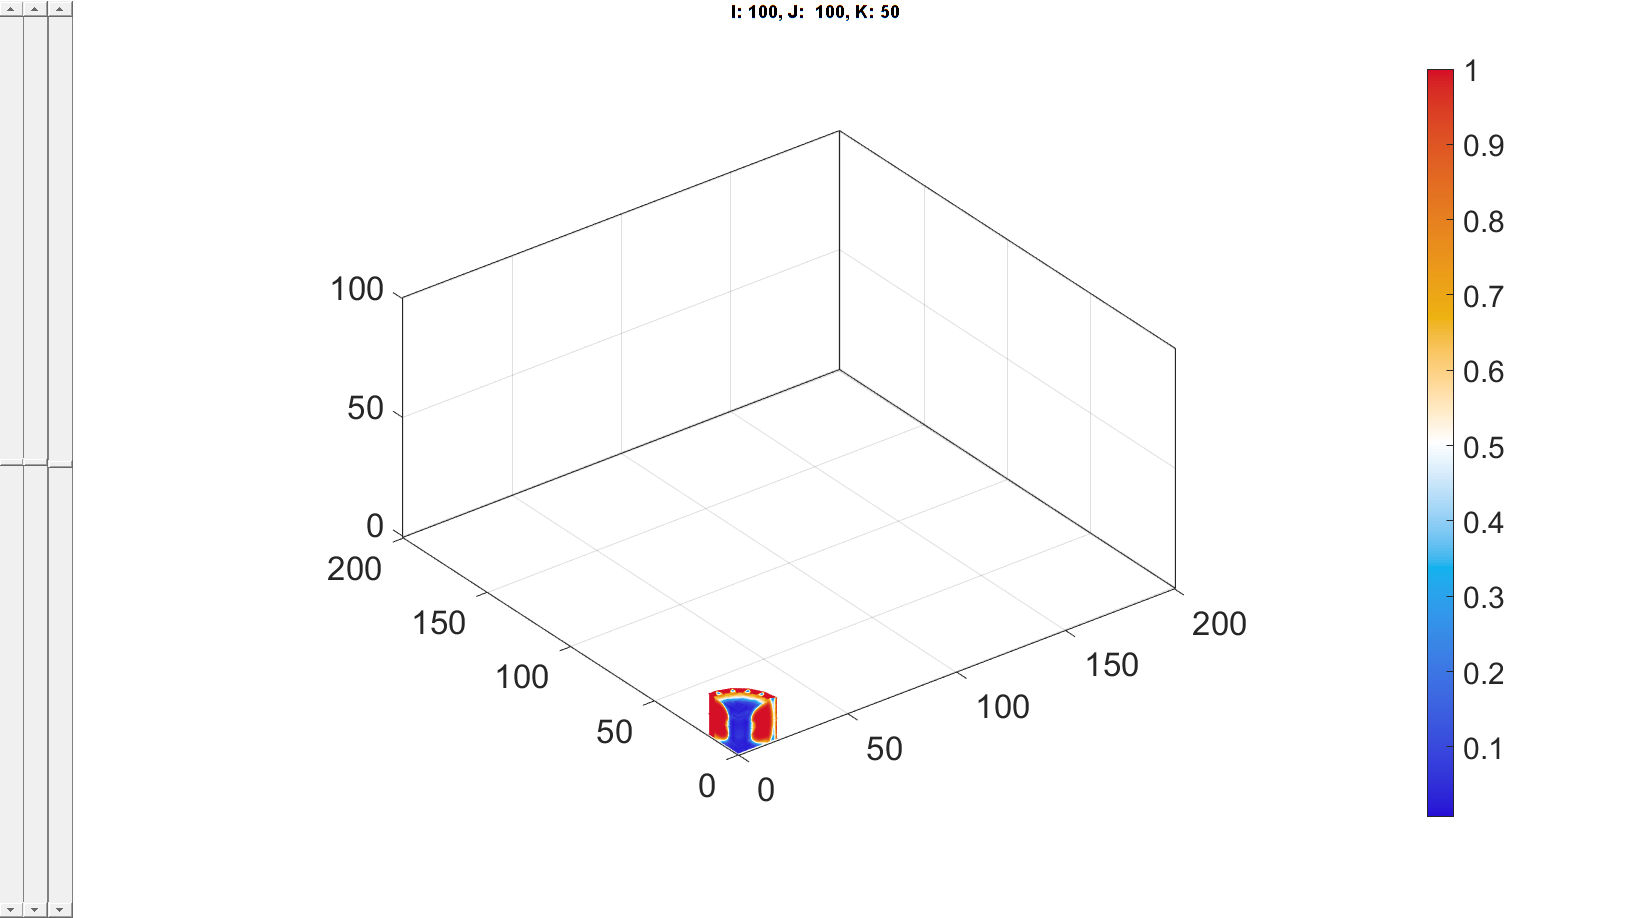

F = scatteredInterpolant(x, y, z, infill, 'linear', 'none');

rhoGrid = F(Xq, Yq, Zq);

slice(Xq, Yq, Zq, rhoGrid, 0, 0, [0.5 9 17.5]);
shading interp;
colorbar;

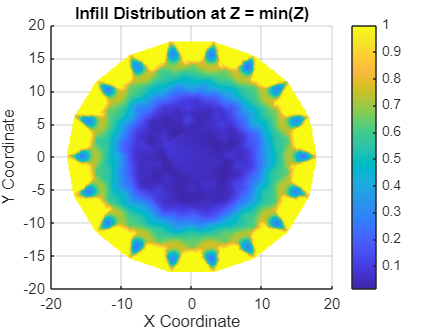

% Infill Distribution
cFigure;
surf(Xq(:,:,2), Yq(:,:,2), rhoGrid(:,:,2), 'EdgeColor', 'none');
colorbar;
title('Infill Distribution at Z = min(Z)');
xlabel('X Coordinate');
ylabel('Y Coordinate');
zlabel('Von Mises Stress');
view(2);

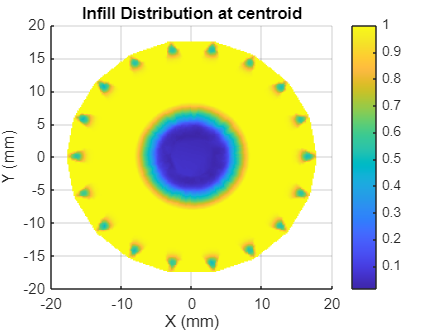


halfwayZ = ceil(size(Xq,3)/2);
cFigure;
surf(Xq(:,:,halfwayZ), Yq(:,:,halfwayZ), rhoGrid(:,:,halfwayZ), 'EdgeColor', 'none');
colorbar;
title('Infill Distribution at centroid');
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Infill');
view(2);

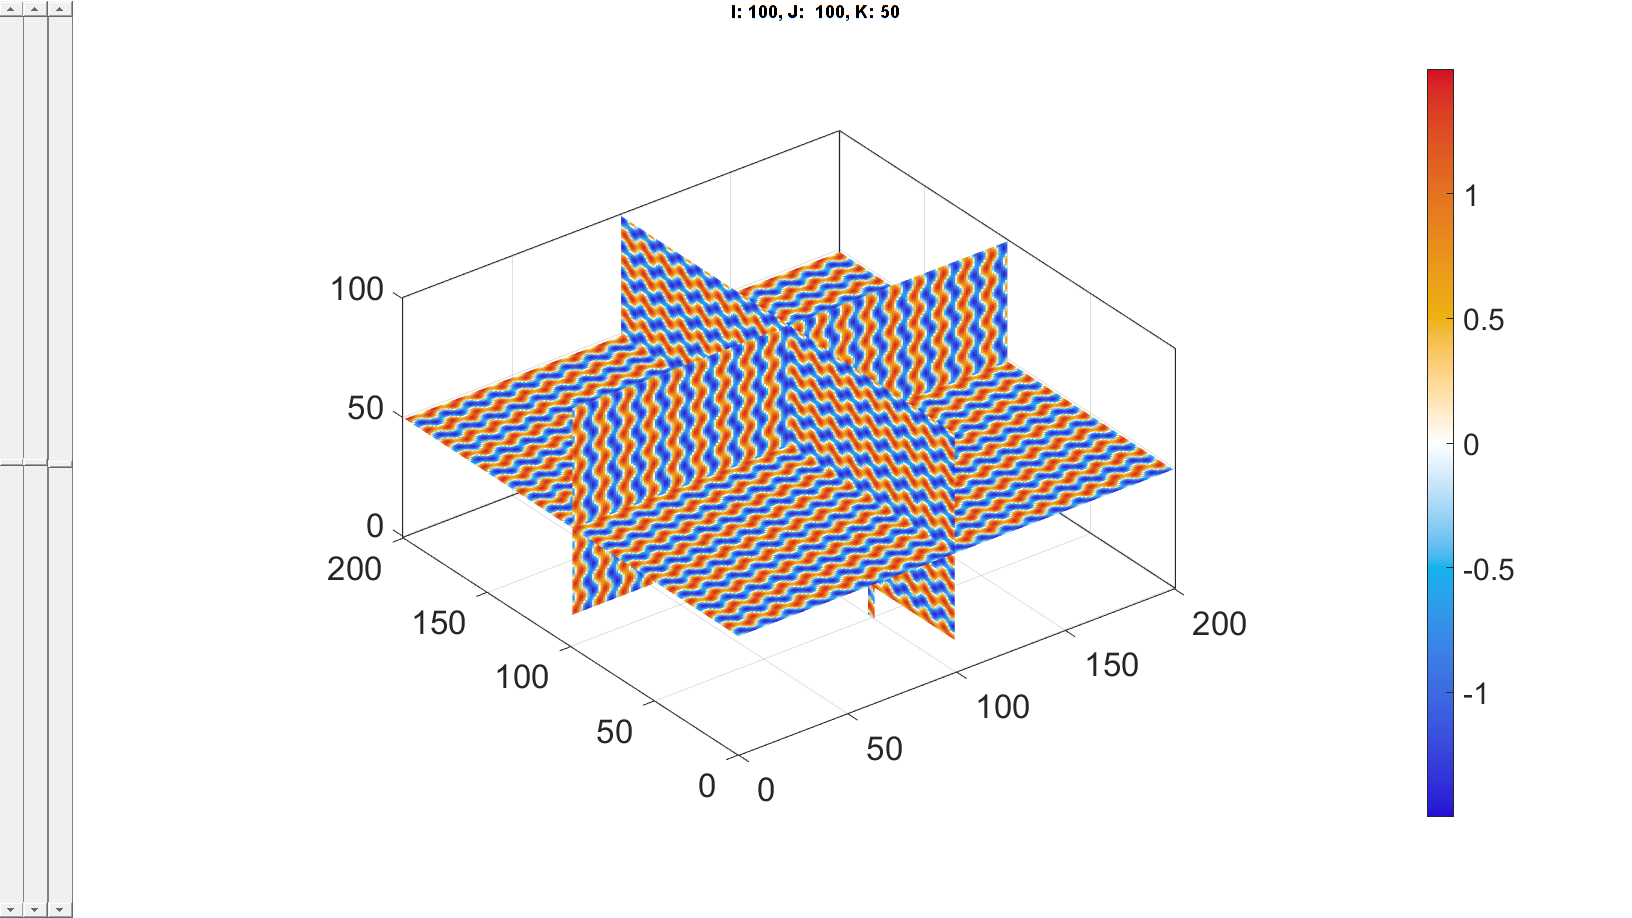

% Parameters
k = pi; % k is grid size

% Generate TPMS function S
S = sin(k*Xq).*cos(k*Yq) + sin(k*Yq).*cos(k*Zq) + cos(k*Xq).*sin(k*Zq);

% Mapping the density to the equivalent gyroid levelSet field
S_flat = S(:);
sorted_S = sort(S_flat);
n = numel(sorted_S);
percentiles = (1:n)/n; % Percentiles from 0 to 1 (exclusive)

target_percentiles = 1 - rhoGrid;
beta = interp1(percentiles, sorted_S, target_percentiles, 'pchip');
beta = max(min(beta, max(sorted_S)), min(sorted_S));

% Generate Sg and extract isosurface
Sg = S - beta;

[Fg,Vg] = isosurface(Xq,Yq,Zq,Sg,0);
[Fgc,Vgc] = isocaps(Xq,Yq,Zq,Sg,0);

[Fsn,Vsn,Csn]=joinElementSets({Fg,Fgc},{Vg,Vgc});
[Fsn,Vsn]=patchCleanUnused(Fsn,Vsn); % Remove unused nodes
[Fsn,Vsn]=mergeVertices(Fsn,Vsn); % Merge nodes

S(~insideMask) = NaN; % note that insideMask is retrieved and reliant on TopOpt.mlx (ensure consistent "n")
sv3(S); colormap warmcold;

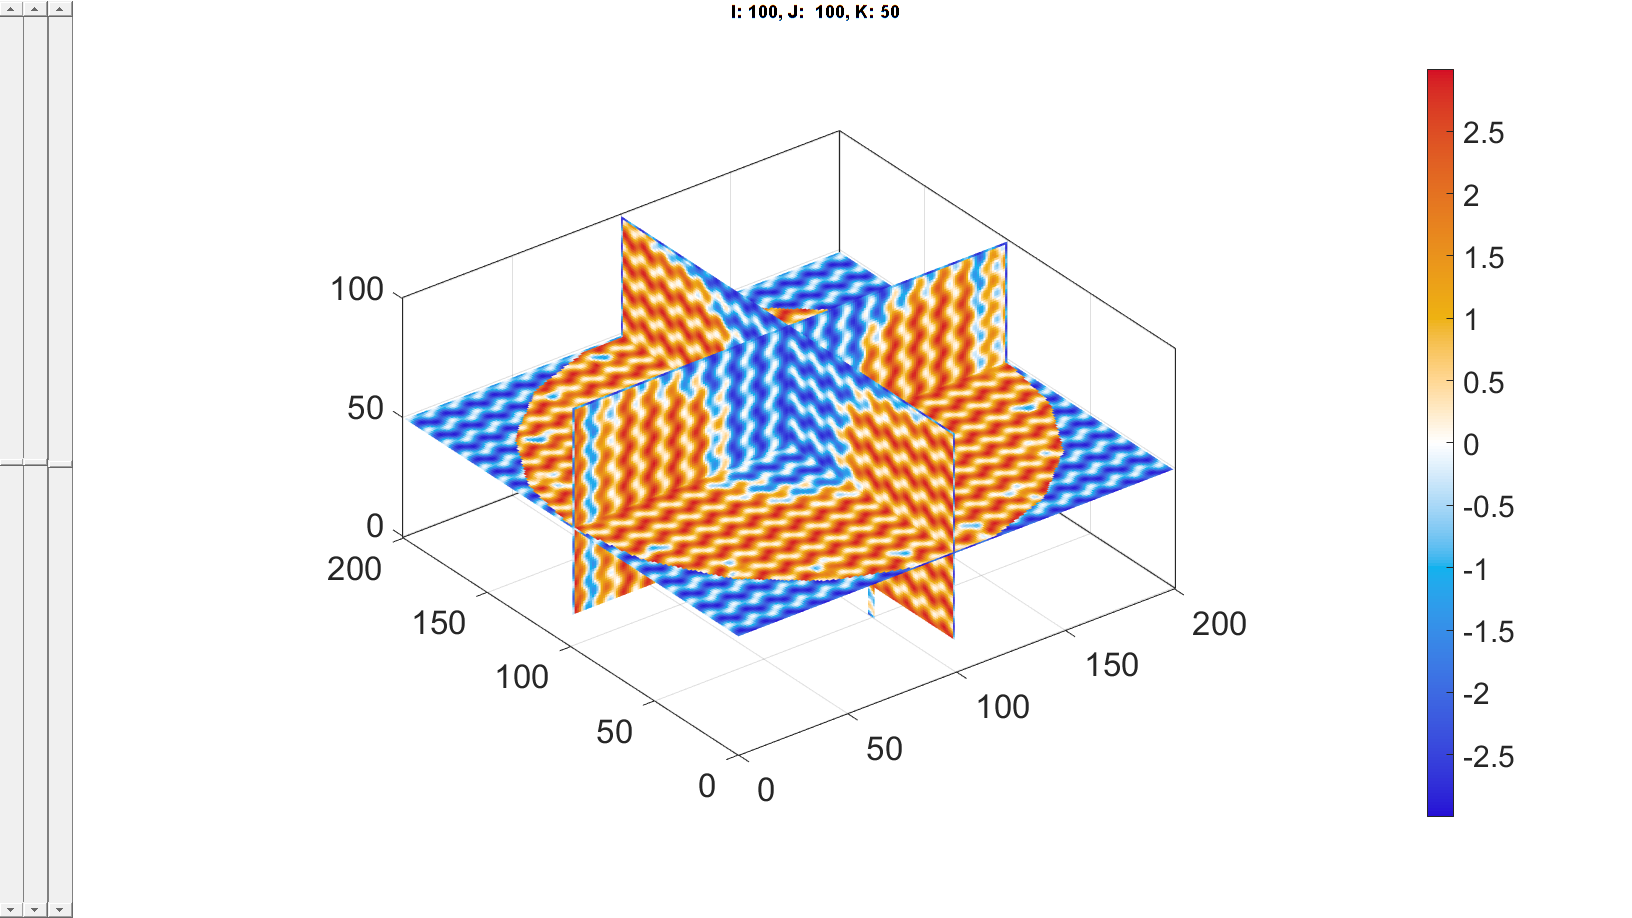

Sg(~insideMask) = NaN;
sv3(Sg); colormap warmcold;

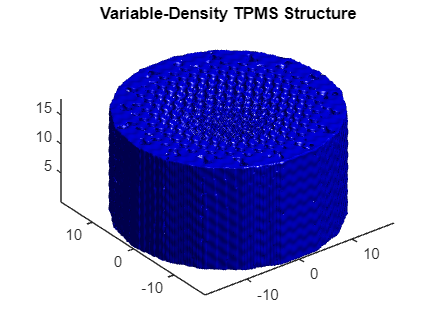


% Visualize
cFigure;
patch('Faces', Fsn, 'Vertices', Vsn, 'FaceColor', 'blue', 'EdgeColor', 'none');
view(3); axis equal; camlight; lighting gouraud;
title('Variable-Density TPMS Structure');

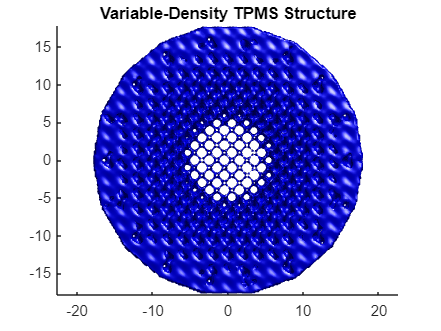


cFigure;
patch('Faces', Fsn, 'Vertices', Vsn, 'FaceColor', 'blue', 'EdgeColor', 'none');
view(2); axis equal; camlight; lighting gouraud;
title('Variable-Density TPMS Structure');

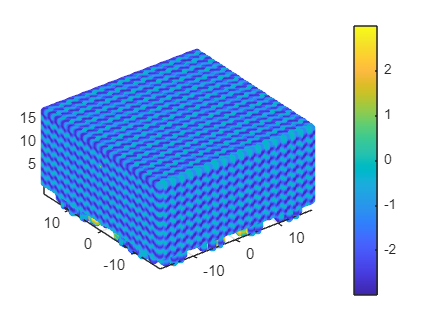

cFigure;  
scatter3(Xq(:),Yq(:),Zq(:),20,Sg(:),'filled');
axis tight; axis equal; 
colorbar;

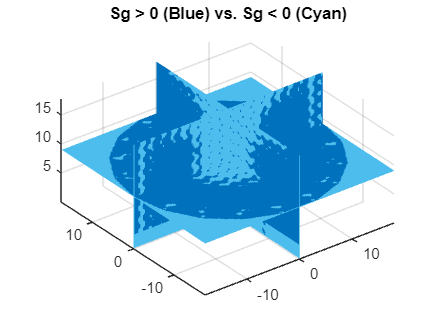

% Create binary mask (1 where Sg > 0, 0 where Sg <= 0)
binary_mask = Sg > 0;

% Define slice positions (e.g., midpoints)
x_slice = 0;  % Mid-X
y_slice = 0;  % Mid-Y
z_slice = max(Zq(:))/2;  % Mid-Z

% Plot slices with binary colors
slice(Xq, Yq, Zq, double(binary_mask), x_slice, y_slice, z_slice);
colormap([0.3010, 0.7450, 0.9330; 0, 0.4470, 0.7410]); % [Blue for 0 (Sg <= 0), Red for 1 (Sg > 0)]
shading flat;

axis tight equal;
colorbar('off'); % Remove colorbar
title('Sg > 0 (Blue) vs. Sg < 0 (Cyan)');

meanZ = mean(Vsn(:,3));

P = [0, 0, meanZ]; % Cut plane point
n = [0, 0, 1]; % Z Normal

snapTolerance = mean(patchEdgeLengths(Fsn, Vsn)) / 100;
% Slice
[Fc, Vc, ~, logicSide, Eb] = triSurfSlice(Fsn, Vsn, [], P, n, snapTolerance);

cFigure; hold on;
gpatch(Fsn, Vsn, 'kw', 'none', 0.01); % transparent original
gpatch(Fc(logicSide,:), Vc, 'rw', 'k', 1); % sliced mesh
gpatch(Eb, Vc, 'none', 'b', 1); % intersections

% Enhance visualization
axisGeom;
camlight headlight;
colormap gjet;
icolorbar;
title('Sliced Mesh Visualization');
drawnow;

savePath = 'D:\TechnicalReport\Variable-TPMS-Figures\TopOpt-From_nTop'
saveFigures(savePath,true,1)